# Problema 7 

## Seria Maclaurin pentru $e^x$ = $\sum_{n+0}^{\infty } \frac{x^n }{n!}$

%f = exp(x)
%T2E = taylor(f, x, 0, 'Order', 3)
%T3E = taylor(f, x, 0, 'Order', 4)
%T4E = taylor(f, x, 0, 'Order', 5)
%T5E = taylor(f, x, 0, 'Order', 6)

function T_maclaurin = maclaurin_exp(N)

    syms x;
    T_maclaurin = 0; % Inițializăm seria cu 0
    
    % Calculăm suma primilor N termeni folosind formula seriei Maclaurin
    for n = 0:N
        term = x^n / factorial(n); % Termenul general al seriei
        T_maclaurin = T_maclaurin + term;
    end
end

% Generăm polinoamele Maclaurin pentru e^x de ordin diferit
syms x;
T2 = maclaurin_exp(2);
T3 = maclaurin_exp(3);
T4 = maclaurin_exp(4);
T5 = maclaurin_exp(5);

% Afișare rezultate
disp('Seriile Maclaurin pentru e^x:');

Seriile Maclaurin pentru e^x:


disp(['T2(x): ', char(T2)]);

T2(x): x + x^2/2 + 1


disp(['T3(x): ', char(T3)]);

T3(x): x + x^2/2 + x^3/6 + 1


disp(['T4(x): ', char(T4)]);

T4(x): x + x^2/2 + x^3/6 + x^4/24 + 1


disp(['T5(x): ', char(T5)]);

T5(x): x + x^2/2 + x^3/6 + x^4/24 + x^5/120 + 1


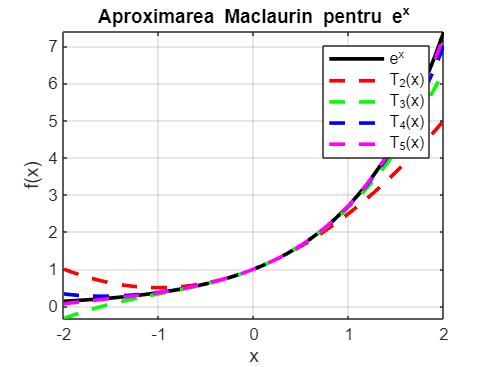


% Plotare funcție originală și aproximările Maclaurin
figure
fplot(exp(x), [-2, 2], 'k', 'LineWidth', 2)
hold on
fplot(T2, [-2, 2], 'r--', 'LineWidth', 2)
fplot(T3, [-2, 2], 'g--', 'LineWidth', 2)
fplot(T4, [-2, 2], 'b--', 'LineWidth', 2)
fplot(T5, [-2, 2], 'm--', 'LineWidth', 2)
legend('e^x', 'T_2(x)', 'T_3(x)', 'T_4(x)', 'T_5(x)')
title('Aproximarea Maclaurin pentru e^x')
xlabel('x'); ylabel('f(x)')
grid on

## Seria Maclaurin pentru $\ln \left(1+x\right)$ = $\sum_{n=0}^{\infty } {\left(-1\right)}^n \frac{x^{n+1} }{n+1}$ 

%g = log(1+x)

%T2_g = taylor(g, x, 0, 'Order', 3)
%T3_g = taylor(g, x, 0, 'Order', 4)
%T4_g = taylor(g, x, 0, 'Order', 5)
%T5_g = taylor(g, x, 0, 'Order', 6)

function T_maclaurin = maclaurin_ln(N)
    % Această funcție calculează seria Maclaurin pentru ln(1+x) până la N termeni
    
    syms x;
    T_maclaurin = 0; % Inițializăm seria cu 0
    
    % Calculăm suma primilor N termeni folosind formula seriei Maclaurin
    for n = 1:N  % Corecție: începe de la n = 1
        term = (-1)^(n-1) * x^n / n; % Corecție: exponent corectat
        T_maclaurin = T_maclaurin + term;
    end
end

% Generăm polinoamele Maclaurin pentru ln(1+x) de ordin diferit
syms x;

T2 = maclaurin_ln(2);
T3 = maclaurin_ln(3);
T4 = maclaurin_ln(4);
T5 = maclaurin_ln(5);

% Afișare rezultate
disp('Seriile Maclaurin pentru ln(1+x):');

Seriile Maclaurin pentru ln(1+x):


disp(['T2(x): ', char(T2)]);

T2(x): x - x^2/2


disp(['T3(x): ', char(T3)]);

T3(x): x - x^2/2 + x^3/3


disp(['T4(x): ', char(T4)]);

T4(x): x - x^2/2 + x^3/3 - x^4/4


disp(['T5(x): ', char(T5)]);

T5(x): x - x^2/2 + x^3/3 - x^4/4 + x^5/5


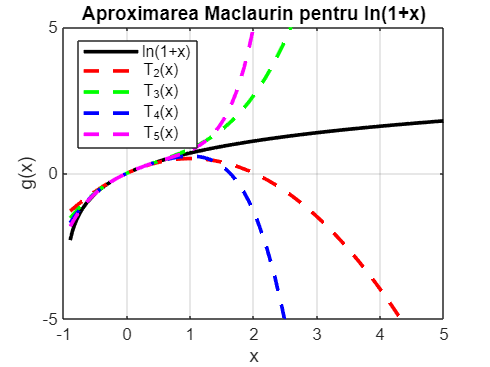


% Funcția exactă ln(1+x) fără a folosi serie
ln_func = @(x) log(1 + x);

% Plot actualizat cu domeniu mai potrivit
figure
fplot(ln_func, [-0.9, 5], 'k', 'LineWidth', 1); hold on;
fplot(matlabFunction(T2), [-0.9, 5], 'r--', 'LineWidth', 1);
fplot(matlabFunction(T3), [-0.9, 5], 'g--', 'LineWidth', 1);
fplot(matlabFunction(T4), [-0.9, 5], 'b--', 'LineWidth', 1);
fplot(matlabFunction(T5), [-0.9, 5], 'm--', 'LineWidth', 1);

ylim([-5, 5]); % Ajustăm pentru a evita valori greșite

legend('ln(1+x)', 'T_2(x)', 'T_3(x)', 'T_4(x)', 'T_5(x)', 'Location', 'NorthWest');
title('Aproximarea Maclaurin pentru ln(1+x)');
xlabel('x'); ylabel('g(x)');
grid on;